# 4.4 实序列 FFT：一个 N 点 FFT 算两个 N 点实序列；一个 N 点 FFT 算一个 2N 点实序列

在 MATLAB 编辑器中打开，点击“运行”；或逐节运行。仅使用基础 MATLAB。

clearvars;
LIVE = strcmp(getenv('DSP_LIVE'), '1');
if LIVE, newpanel = @(varargin) figure('Color','w','Position',[80 80 640 420]); else, newpanel = @(varargin) nexttile(varargin{:}); end
if LIVE, set(groot, 'defaultLegendLocation', 'southoutside'); else, set(groot, 'defaultLegendLocation', 'best'); end
outdir = fullfile(fileparts(mfilename('fullpath')), 'results');
if ~exist(outdir, 'dir'), mkdir(outdir); end

## 演示1：两个 N 点实序列合成一个复序列，一次 FFT 分开（教材 4.4.2）

x(n)=x1(n)+j·x2(n)，X1(k)=[X(k)+X*(N−k)]/2，X2(k)=[X(k)−X*(N−k)]/(2j)

N = 64; n = 0:N-1; rng(20260918);
x1 = cos(2*pi*4*n/N) + 0.3*randn(1, N);          % 两个彼此独立的实序列
x2 = 0.8*sin(2*pi*11*n/N) + 0.3*randn(1, N);
z = x1 + 1i*x2; Z = fft(z);
Zc = conj(Z(mod(-(0:N-1), N) + 1));               % X*(N−k)，k=0 时取 X*(0)
X1 = (Z + Zc)/2; X2 = (Z - Zc)/(2i);
err1 = max(abs(X1 - fft(x1))); err2 = max(abs(X2 - fft(x2)));

## 演示2：一个 2N 点实序列，用一个 N 点 FFT（教材 4.4.3）

偶序号样本作实部、奇序号样本作虚部：z(n)=x(2n)+j·x(2n+1)；分出 A(k)、B(k) 后用一次蝶形合成 X(k)

M = 128;                                          % 2N = 128，N = 64
m = 0:M-1; xLong = cos(2*pi*7*m/M) + 0.5*cos(2*pi*30*m/M + 1) + 0.2*randn(1, M);
zz = xLong(1:2:end) + 1i*xLong(2:2:end); ZZ = fft(zz);   % 64 点 FFT
ZZc = conj(ZZ(mod(-(0:N-1), N) + 1));
A = (ZZ + ZZc)/2; B = (ZZ - ZZc)/(2i);           % 偶样本、奇样本各自的 N 点 DFT
k = 0:N-1; Wk = exp(-2i*pi*k/M);
Xfull = [A + Wk.*B, A - Wk.*B];                   % X(k) 与 X(k+N)
errLong = max(abs(Xfull - fft(xLong)));

## 演示3：省了多少——复乘次数

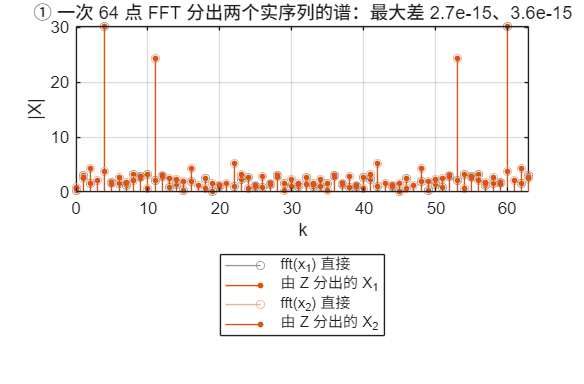

mFFT = @(N) N/2*log2(N);
costTwoSeparate = 2*mFFT(N);                      % 两个 N 点 FFT（把实序列当复序列各做一次）
costTwoTrick = mFFT(N);                           % 一次 N 点 FFT + 少量加减
costLongDirect = mFFT(M);                         % 直接做 2N 点 FFT
costLongTrick = mFFT(N) + N;                      % 一次 N 点 FFT + N 次复乘（W^k·B）

if ~LIVE, f1 = figure('Name','03 实序列 FFT','Color','w','Position',[60 40 1250 900]); end
if ~LIVE, tiledlayout(2,2,'TileSpacing','compact','Padding','compact'); end
newpanel(); stem(k, abs(fft(x1)), 'MarkerSize', 5, 'Color', [0.6 0.6 0.6]); hold on; stem(k, abs(X1), 'filled', 'MarkerSize', 3);
stem(k, abs(fft(x2)), 'MarkerSize', 5, 'Color', [0.9 0.7 0.6]); stem(k, abs(X2), 'filled', 'MarkerSize', 3, 'Color', [0.85 0.33 0.1]);
grid on; xlim([0 N-1]);
title(sprintf('① 一次 64 点 FFT 分出两个实序列的谱：最大差 %.1e、%.1e', err1, err2)); xlabel('k'); ylabel('|X|');
legend('fft(x_1) 直接','由 Z 分出的 X_1','fft(x_2) 直接','由 Z 分出的 X_2');

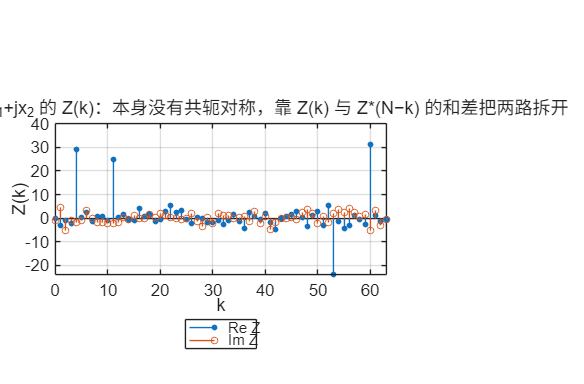

newpanel(); stem(k, real(Z), 'filled', 'MarkerSize', 3); hold on; stem(k, imag(Z), 'MarkerSize', 4, 'Color', [0.85 0.33 0.1]);
grid on; xlim([0 N-1]);
title('② 合成序列 z=x_1+jx_2 的 Z(k)：本身没有共轭对称，靠 Z(k) 与 Z*(N−k) 的和差把两路拆开'); xlabel('k'); ylabel('Z(k)');
legend('Re Z','Im Z');

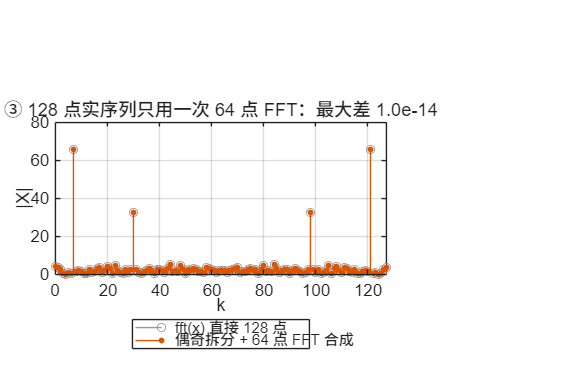

newpanel(); stem(0:M-1, abs(fft(xLong)), 'MarkerSize', 5, 'Color', [0.6 0.6 0.6]); hold on; stem(0:M-1, abs(Xfull), 'filled', 'MarkerSize', 3);
grid on; xlim([0 M-1]);
title(sprintf('③ 128 点实序列只用一次 64 点 FFT：最大差 %.1e', errLong)); xlabel('k'); ylabel('|X|');
legend('fft(x) 直接 128 点','偶奇拆分 + 64 点 FFT 合成');

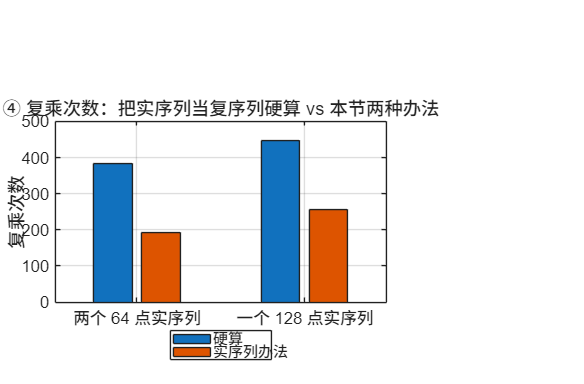

newpanel(); bar([costTwoSeparate costTwoTrick; costLongDirect costLongTrick]); grid on;
set(gca, 'XTickLabel', {'两个 64 点实序列', '一个 128 点实序列'}); ylabel('复乘次数');
title('④ 复乘次数：把实序列当复序列硬算 vs 本节两种办法'); legend('硬算','实序列办法');

if ~LIVE, sgtitle('实序列只有 N 个自由变量：用共轭对称把一次复 FFT 的算力用满'); end
if ~LIVE, prepare_export(f1); end
if ~LIVE, exportgraphics(f1, fullfile(outdir, '03-real-fft.png'), 'Resolution', 150); end

## 教师核验

assert(err1 < 1e-11 && err2 < 1e-11, '两实序列拆分不符');
assert(errLong < 1e-11, '2N 点实序列合成不符');
assert(costTwoTrick*2 == costTwoSeparate && costLongTrick < costLongDirect, '运算量比较不符');
metrics = struct('matlab_version', version, 'run_at', char(datetime('now','Format','yyyy-MM-dd HH:mm:ss')), ...
    'N', N, 'two_real_err', [err1 err2], 'M', M, 'long_real_err', errLong, ...
    'cost_two_separate', costTwoSeparate, 'cost_two_trick', costTwoTrick, 'cost_long_direct', costLongDirect, 'cost_long_trick', costLongTrick, ...
    'all_checks_passed', true);
fid = fopen(fullfile(outdir, 'verification-real-fft.json'), 'w', 'n', 'UTF-8'); assert(fid >= 0);
fprintf(fid, '%s\n', jsonencode(metrics, PrettyPrint=true)); fclose(fid);
disp(metrics); fprintf('\n课堂图已保存到：%s\n', outdir);

       matlab_version: '25.2.0.3360999 (R2025b) Update 7'
               run_at: '2026-09-18 19:56:17'
                    N: 64
         two_real_err: [2.7308e-15 3.5596e-15]
                    M: 128
        long_real_err: 1.0049e-14
    cost_two_separate: 384
       cost_two_trick: 192
     cost_long_direct: 448
      cost_long_trick: 256
    all_checks_passed: 1


课堂图已保存到：C:\Users\Administrator\AppData\Local\Temp\Editor_lhbfa\results



function prepare_export(fig)
axesList = findall(fig, 'Type', 'axes');
for a = 1:numel(axesList), axesList(a).Toolbar.Visible = 'off'; end
drawnow;
end